# Multivariate linear regression

## Data formating

Add bias term

X_tr_bias = [ones(1, size(X_tr, 2)); X_tr];
X_val_bias = [ones(1, size(X_val, 2)); X_val];

## Training

regularization = 0;
I = eye(size(X_tr_bias, 1));
I(1, 1) = 0; % Don't regularize bias term
weights = Y_tr * X_tr_bias' * pinv(X_tr_bias * X_tr_bias' + regularization * I);

## Summary

Y_tr_pred = weights * X_tr_bias;
Y_val_pred = weights * X_val_bias;

trainPerformance = mse(Y_tr_pred, Y_tr);
valPerformance = mse(Y_val_pred, Y_val);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);

Rendimiento en el conjunto de entrenamiento: 0.011202


disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

Rendimiento en el conjunto de validación: 0.011755


# Performance analysis

## Complete timeseries

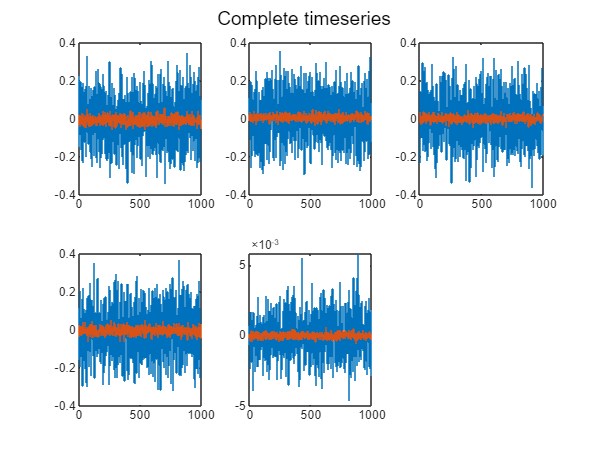

X_bias = [ones(1, size(X, 2)); X];
pred = weights * X_bias;
figure
subplot(ceil(Noutputs/3), 3, 1)
stairs(1:Nsamples, Y(1, :))
hold on
stairs(1:Nsamples, pred(1, :))
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    stairs(1:Nsamples, Y(idx, :))
    hold on
    stairs(1:Nsamples, pred(idx, :))
    hold off
end
sgtitle('Complete timeseries');

## Error histogram

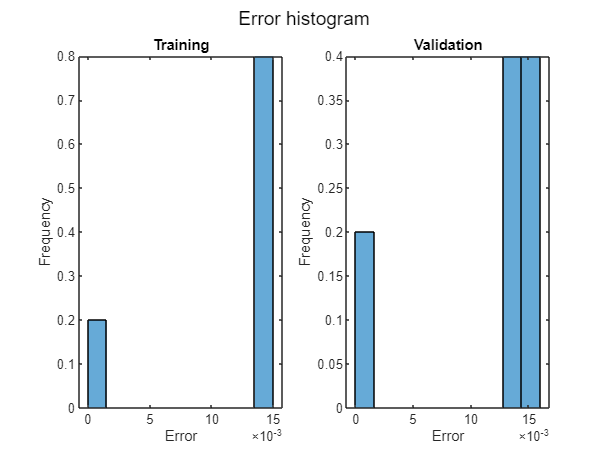

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 10, 'Normalization', 'probability')
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 10, 'Normalization', 'probability')
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

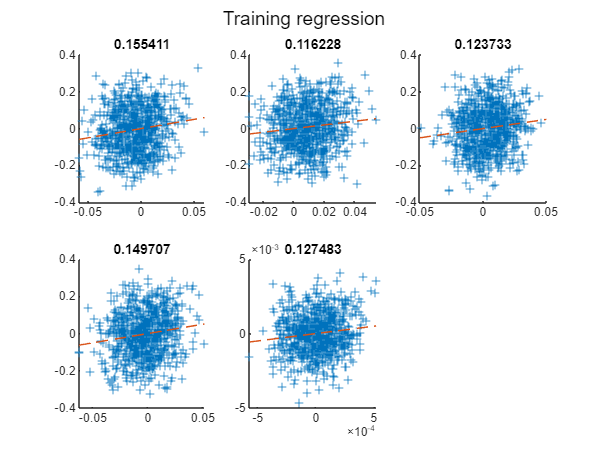

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

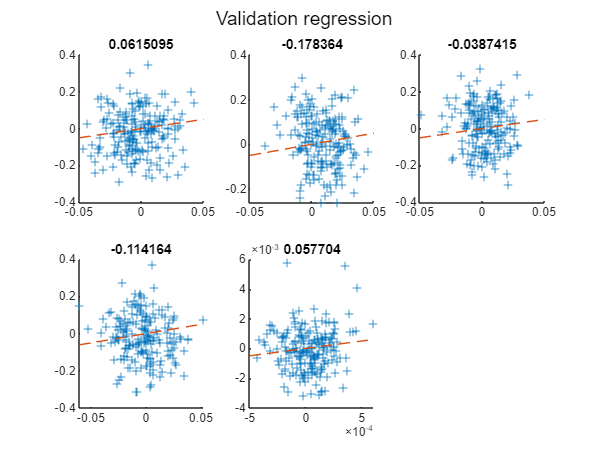


figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

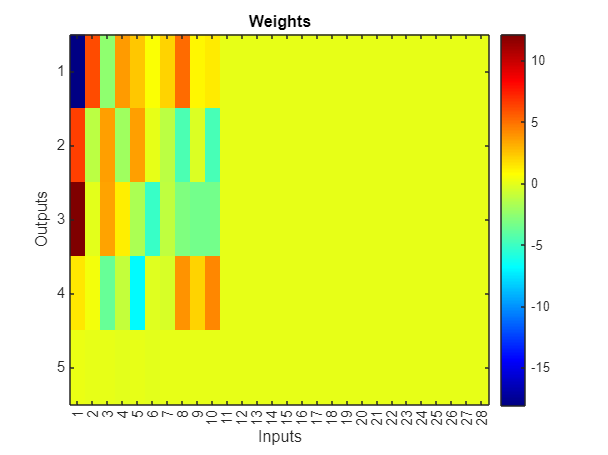

figure
imagesc(weights)
colorbar
colormap("jet")
title('Weights')
xlabel('Inputs')
ylabel('Outputs')
xticks(1:size(weights, 2))
yticks(1:size(weights, 1))

Near zero weights

min(min(abs(weights)))

ans = 1.0510e-06

weights_treshold = 0.01 * max(max(abs(weights)))

weights_treshold = 0.1810

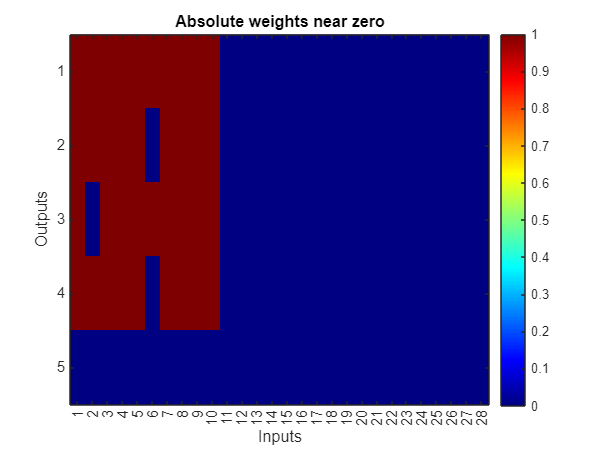

weights(abs(weights) <= weights_treshold) = 0;
weights(abs(weights) > weights_treshold) = 1;

figure
imagesc(weights)
colorbar
colormap("jet")
title('Absolute weights near zero')
xlabel('Inputs')
ylabel('Outputs')
xticks(1:size(weights, 2))
yticks(1:size(weights, 1))